# **各向同性的直流电型隐形装置**

**        所谓直流电型隐身衣，是导电媒质中针对特定区域的隐身装置。通过将人工制作的特殊导电材料层覆盖在目标周围,能够控制电流线(电力线)绕过目标物体,从而使得该区域不被探测者所发现。近年来，利用复杂电阻网络模拟非均匀和各向异性电导率的变换光学器件越来越受人们的关注。也有一些学者提出了一种直接求解电导体内拉普拉斯方程来实现对直流电场的控制的方法，从而实现稳恒电场领域的电磁隐形。下图给出的是一个圆柱体稳恒电场隐形衣的装置示意图。图中半径为b的圆柱部分原本放置在稳恒电场**${\mathrm{E}}_0$**中。各区域内均满足**$\vec{J} =\sigma \cdot \vec{E}$，**通过外场与导电媒质的相互作用使得圆柱环外的电场被扰动。因此，只要通过探察外围电场是否会被干扰，就可以判断环境里面是否有金属导体柱存在，或者说，该金属柱有没有被隐形。为此,在金属柱外面套一个内、外半径分别为 b、c 的同心圆环同样会影响外场分布。但如果合理设计套层的尺寸、电导率的大小,使其在外加匀强电场的作用下，对外部电场没有任何扰动，那就能达到对内部金属柱隐形的目的。**

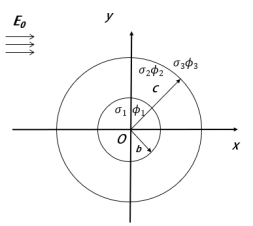

**        下面利用圆柱坐标系下的电势的拉普拉斯方程求解来对上述问题进行分析。忽略柱体高度引起的误差，可以认为是一个平面场问题。在稳恒电场中，各区域电势均满足**


$$\nabla^2 \phi_i =0\textrm{，i}=1,2,3$$


**        各分界面上的边值关系为**


$$\left\lbrace \begin{array}{ll}
{\phi_1 |}_{r=b} ={\phi_2 |}_{r=b} , & {\sigma_1 \frac{\partial \phi_1 }{\partial r}|}_{r=b} ={\sigma_2 \frac{\partial \phi_2 }{\partial r}|}_{r=b} \\
{\phi_2 |}_{r=c} ={\phi_3 |}_{r=c} , & {\sigma_2 \frac{\partial \phi_2 }{\partial r}|}_{r=c} ={\sigma_3 \frac{\partial \phi_3 }{\partial r}|}_{r=c} 
\end{array}\right.$$


**        考虑实际情况，r>c的区域为背景材料,电导率可表示为**$\sigma_b$，**即有**$\sigma_3$=$\sigma_b$**。用分离变量法可求出由平面极坐标系中拉普拉斯方程的一般解为**


$$\phi_i =\sum_{m=1}^{\infty } \left(A_m^{\left(i\right)} r^m +B_m^{\left(i\right)} r^{-m} \right)\left(C_m^{\left(i\right)} \textrm{cosm}\varphi +D_m^{\left(i\right)} \textrm{sinm}\varphi \right)\;\;\;\;\;\left(i=1,2,3\right)$$


**        可得各个区域中的电势分布如下**


$$\begin{array}{l}
\phi_1 =A_1^{\left(1\right)} \textrm{rcos}\varphi \\
\phi_2 =\left(A_1^{\left(2\right)} r+\frac{B_1^{\left(2\right)} }{r}\right)\cos \varphi \\
\phi_3 =\left(-{\mathrm{E}}_0 r+\frac{B_1^{\left(3\right)} }{r}\right)\cos \varphi 
\end{array}$$


**        将各个区域的电势表达式代入，求解可得 **$B_1^{\left(3\right)}$**的表达式为**


$${B_1^{\left(3\right)} =E_0 c}^2 \frac{\sigma_2 \left(Q_1 -Q_2 \right)-\sigma_b \left(Q_1 +Q_2 \right)}{\sigma_2 \left(Q_1 -Q_2 \right)+\sigma_b \left(Q_1 +Q_2 \right)}$$


**        其中，**$Q_1 =c^2 \left(1+\frac{\sigma_1 }{\sigma_2 }\right),Q_2 =b^2 \left(1-\frac{\sigma_1 }{\sigma_2 }\right)$

**        令**$B_1^{\left(3\right)} =0$**，可得隐形环半径关系为：**


$$c=b\sqrt{\frac{\left(\sigma_2 -\sigma_1 \right)\left(\sigma_2 +\sigma_b \right)}{\left(\sigma_2 +\sigma_1 \right)\left(\sigma_2 -\sigma_b \right)}}$$


**        由上式进行设计包围金属柱的圆柱环，可满足**$B_1^{\left(3\right)}$**恒等于零，这就意味着扰动场始终为零。从而在背景材料中，无论是金属柱附近还是远处，场分布都是均匀的。换句话说，对于该金属柱来讲，对外加电场无干扰，就像整个空间全部都是背景材料，即金属柱被隐形了。**

**        我们将金属柱(中心区域)、隐身外壳和背景材料分别假定为不锈钢(**$\sigma_1 =1\ldotp 3*{10}^{6\;} S\;m^{-1}$**)、铜(**$\sigma_2 =5\ldotp 9*{10}^{7\;} S\;m^{-1}$**)和铁(**$\sigma_b =1*{10}^{7\;} S\;m^{-1}$**)，根据隐形环半径关系，当b=2.5cm时，得到c =2.9cm。**

**        用pdetool仿真：**

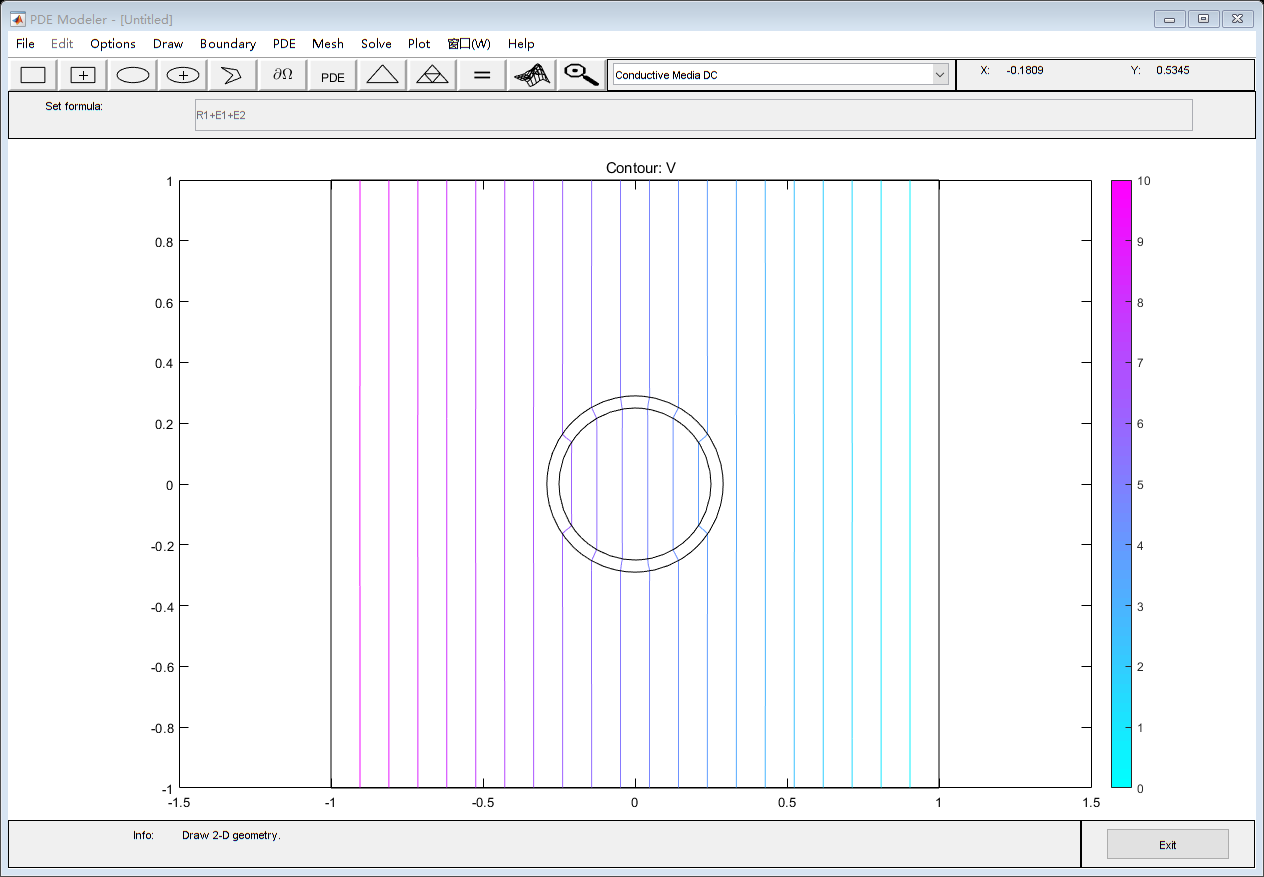

dc_Electric_Invisibility_Cloak

**        仿真结果如上所示，可见在外加匀强电场的作用下，外部电场没有任何扰动，即达到了对内部金属柱隐形的目的。**

function dc_Electric_Invisibility_Cloak
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',8);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 1 -1],'R1');
    pdeellip(0,0,0.28999999999999998,0.28999999999999998,...
    0,'E1');
    pdeellip(0,0,0.25,0.25,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+E1+E2')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '10')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    
    % PDE coefficients:
    pdeseteq(1,...
    '10000000!1300000!59000000',...
    '0.0!0.0!0.0',...
    '0!0!0',...
    '1.0!1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['10000000!1300000!59000000 ';...
    '0!0!0                     '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1518','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 0 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

- 参考文献：

                [1]Han, T., Ye, H., Luo, Y., Yeo, S.P., Teng, J., Zhang, S. and Qiu, C.-W. (2014), Manipulating DC Currents with Bilayer Bulk Natural Materials. Adv. Mater., 26: 3478-3483. 